# Home-work 2

## Task

We want to cross the river, and our boat is going twice as slow as the river's current. In which  direction (angle!) do we have to steer the boat so that the distance to the starting point is the  shortest? 


$$d(\alpha) = \frac{L \cdot cos(\alpha)}{sin(\alpha)} + \frac{L \cdot \eta}{sin(\alpha)} \quad \text{(set L=1 width of the river is normalised)}$$


Let $\eta$ be a ratio of $V_r$ and $Vb_$, where $V_r$ is the velocity of river and $V_b$ velocity of boat.


$$\eta = \frac{V_r}{V_b}$$


## **Part (a)**

*Explain (sketch vectors) what means if *$\eta<1$*, *$\eta=1$* and *$\eta>1$*.* 

- $\eta > 1$: the river is faster than the boat

- $\eta = 1$: the river and boat are equally fast

- $\eta < 1$: the boat is faster than the river

## **Part (b)**

*Find optimal angles for *$\eta=1.5$*, *$2.0$*, *$2.5$* and *$3.0$*. * 

Start by defining the function and variables from Task section. We assume that $L=1$, as the instructions say. To find the optimal angle for an $\eta$ value, we have to find the minimum value, which is an extreme point. First we differentiate the function and then we solve it for $a$.

syms a eta
eta_values = [1.5, 2.0, 2.5, 3.0];

d = (1 * cos(a) / sin(a)) + (1 * eta / sin(a));
df = diff(d, a);
d_optimal = solve(df == 0, a);

Now we loop through every $\eta$ value in `eta_values `and find the optimal angle for each value.

disp("finding optimal alpha values for each eta value...")

finding optimal alpha values for each eta value...


for i = 1:length(eta_values)
    sol = subs(d_optimal, eta, eta_values(i));
    numeric_sol = double(sol)
end

numeric_sol =     2.3005
    3.9827


numeric_sol =     2.0944
    4.1888


numeric_sol =     1.9823
    4.3009


numeric_sol =     1.9106
    4.3726


## Part (c)

*Plot four functions on the same plot, for*$\eta=1.5$*, *$2.0$*, *$2.5$* and *$3.0$*.*

First we define an array of $x$-values for the plot with `linspace, `which makes values evenly spaced. Start at $0.1$ and end at $\pi - 0.1$, since we can't have division by 0.

alpha_vals = linspace(0.1, pi-0.1);
alpha_deg = rad2deg(alpha_vals);

For each $\eta$ value we substitute it's value and all of the $\alpha$ values into the function and then we plot the evaluated values.

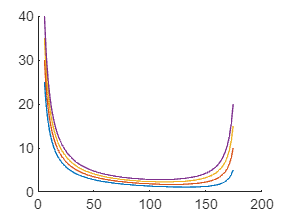

figure
for i = 1:length(eta_values)
    eta = eta_values(i);
    sol = subs(d, eta, eta_values(i));
    sol = eval(subs(sol, a, alpha_vals));
    hold on
    plot(alpha_deg, sol)
end
hold off

## **Part (d)**

*Calculate distance *$d$* (displacement from the origin *$x_0$*) for *$\eta = 2$* and optimal angle *$\alpha = 120$.

Calculate the function's value based on the given data (also convert degrees to radians), then display the result.

sol = subs(d, eta, 2);
sol = eval(subs(sol, a, deg2rad(120)));
fprintf("Displacement for eta = 2 and a = 120:\n%d\n", sol);

Displacement for eta = 2 and a = 120:
2.886751e+00
